# **drawSpring1**

Draw a coil spring 

## Description

## Syntax

drawSpring1(form,r,nc,x1,y1,x2,y2)  

drawSpring1(form,r,nc,x1,y1,'-delta',dx,dy)  

drawSpring1(form,r,nc,x1,y1,'-polar',r,th)  

drawSpring1(__,'-type','flat'|'ext') 

drawSpring1(__,LineSpec) 

p = drawSpring1(__)

## Description

## Method

## Arguments

### Input Arguments

**form   ** --- spring type: 1=flat,2=ext

** r       -**-- radius

** nc      **--- number of circuts

**x1, y1  **--- start point

**x2, y2 **    -- end point

or

** '-polar'|'-rtheta',  r, th** -- polar coordiantes of end point

or

** '-delta', dx, dy **-- delta coordinates of end point

### Optional Name-Value Pair Input Arguments

***LineSpec*** - specifies line properties, see [Line Properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html).

### Optional Output Arguments

**p **- structure with the fields

- p.xk, p.yk - key points:1=start,2=end

- p.color - line color

## Examples

### Example 1

drawInit
x0 = 0; y0=0;nc=3;r=1/2,

r = 0.5000

p0=drawSpring1(1,r,nc,x0,y0,x0,4);
p= drawSpring1(2,r,nc,x0+4,y0,'-rtheta',4,75,'LineWidth',2)

p = struct with fields:
       xk: [4 5.0353]
       yk: [0 3.8637]
    color: [0.8500 0.3250 0.0980]


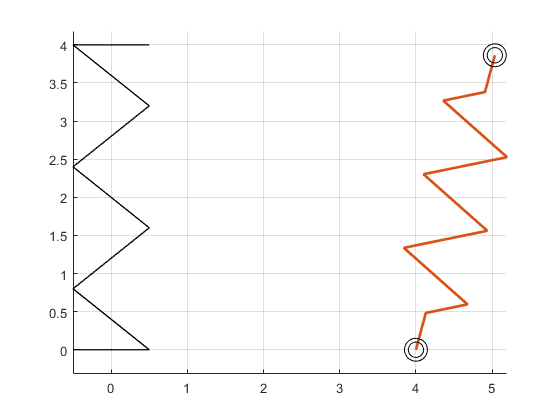

drawDonut(0.3,0.2,p.xk(1),p.yk(1),'k')
drawDonut(0.3,0.2,p.xk(2),p.yk(2),'k')
grid on

## **See Also**

## References